# 2リンクマニピュレータの運動方程式導出とシミュレーション

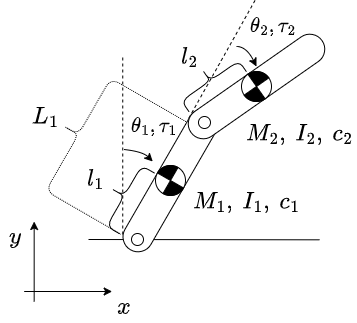

重心と回転軸の間の距離をl、関節の長さをLと分けている。

重心周りの慣性モーメントI、各関節の減衰係数c。

オリジナルは↓

https://www2.kaiyodai.ac.jp/~shimizu/lec/b/rb-2/rb-2.pdf

clear;
syms M_1 M_2 L_1 l_1 l_2 g I_1 I_2 c_1 c_2 real % 物理パラメータ 実数値しかとらないので念のためreal

'syms' には Symbolic Math Toolbox が必要です。

syms theta(t) [2 1] % [theta1(t)、theta2(t)]^T の定義
syms tau(t) [2 1] % [tau1(t)、tau2(t)]^T の定義 

%--- 一般化座標qの定義 ---
% q = theta ←こうしてしまうと、q(1)としたとき、q(t)|t=1の意味になってしまう。
% 台車型倒立振子などで並進移動を組み合わせるなら、q = [theta(t); x(t)];とかすれば良いはず
q = theta(t);
dq = diff(q,t);
ddq = diff(dq,t);
tau = tau(t); % qと同様、tの関数であることを省略表記するための置き換え

%--- 座標の定義と、それらの導関数の記述 ---
x_1 = l_1 * sin(q(1));
y_1 = l_1 * cos(q(1));

x_2 = L_1 * sin(q(1)) + l_2 * sin(q(1)+q(2));
y_2 = L_1 * cos(q(1)) + l_2 * cos(q(1)+q(2));

dx_1 = diff(x_1, q(1))*dq(1) + diff(x_1, q(2))*dq(2);
dx_2 = diff(x_2, q(1))*dq(1) + diff(x_2, q(2))*dq(2);

dy_1 = diff(y_1, q(1))*dq(1) + diff(y_1, q(2))*dq(2);
dy_2 = diff(y_2, q(1))*dq(1) + diff(y_2, q(2))*dq(2);


%--- Lagrange関数の記述 ---
K1 = 1/2*M_1*dx_1^2 + 1/2*M_1*dy_1^2;
K2 = 1/2*M_2*dx_2^2 + 1/2*M_2*dy_2^2;

Krot = 1/2*I_1*dq(1)^2 + 1/2*I_2*(dq(1)+dq(2))^2;

U1 = M_1*g*l_1*cos(q(1));
U2 = M_2*g*L_1*cos(q(1))+M_2*g*l_2*cos(q(1)+q(2));

L = (K1+K2+Krot) - (U1+U2);

D = [c_1*dq(1), c_2*dq(2)]; % 散逸項はあらかじめ微分してある

%--- Lagrange方程式による運動方程式導出---
N = length(q);
for i = 1:N
    dLq(i) = diff(L, dq(i));

    temp = 0;
    for j = 1:N
        temp = temp + diff(dLq(i),dq(j))*ddq(j) + diff(dLq(i),q(j))*dq(j);
    end
    ddLq(i) = temp;

    eq(i) = ddLq(i) - diff(L,q(i)) == -D(i)  + tau(i);
end
eq(1) % 得られた運動方程式の表示
eq(2) % 得られた運動方程式の表示

## 初期値を与えた時の自由振動シミュレーション

L_1 = 2;
l_1 = 1;
l_2 = 1.5;
M_1 = 2;
M_2 = 1;
g = 9.8;
c_1 = 2;
c_2 = 2;
tau1 = 0;
tau2 = 0;
I_1 = 1/M_1*l_1^2; % 一様な剛体棒の慣性モーメント
I_2 = 1/M_2*l_2^2; % 一様な剛体棒の慣性モーメント

eqn_1 = subs(eq(1));
eqn_2 = subs(eq(2));
[V,S] = odeToVectorField(eqn_1,eqn_2); % ベクトルSを置き、高階微分方程式を1階微分方程式Vに置き換え
% S = [theta2 dtheta2 theta1 dtheta1]の順

solveHandler = matlabFunction(V,'vars',{'t','Y'}); 

initCond = [pi/4 0 pi/6 0]; % [theta2=pi/4 dtheta2=0 theta1=pi/6 dtheta1=0]
TimeLentgh = [0 20];
sols = ode45(solveHandler,TimeLentgh,initCond);

## 描画

plot(sols.x,sols.y)
legend('\theta_2' , 'd\theta_2/dt', '\theta_1', 'd\theta_1/dt')
title('Dual Pendulum Test')
xlabel('Time[s]')
ylabel('[rad] or [rad/s]')